# Cleaning Workspace

clear;
close all;
clc;

# Plot Parameters

linewidth  = 2;
markersize = 10;
fontsize   = 20;
fontname   = 'Times New Roman';

bas_size = 0.8;

legend_algo_1 = {'NS','ESEPS','ESMMFS','RS','SOS','CBS','ICIBS','FRBS'};
legend_algo_2 = {'ESEPS','ESMMFS','RS','SOS','CBS','ICIBS','FRBS'};
% legend_algo_1 = {'NS','RS','SOS','CBS','ICIBS','FRBS'};
% legend_algo_2 = {'RS','SOS','CBS','ICIBS','FRBS'};
legend_link   = {'Uplink','Downlink'};
legend_pa     = {'EPA','MMFPA'};

cat_1 = categorical(legend_algo_1);
cat_1 = reordercats(cat_1,legend_algo_1);

cat_2 = categorical(legend_algo_2);
cat_2 = reordercats(cat_2,legend_algo_2);

color = [0.0000 0.4470 0.7410;
         0.8500 0.3250 0.0980;
         0.9290 0.6940 0.1250;
         0.4940 0.1840 0.5560;
         0.4660 0.6740 0.1880;
         0.3010 0.7450 0.9330;
         0.6350 0.0780 0.1840;
         0.5423 0.8950 0.0042;
         0.0430 0.8973 0.2345];

marker = {'o','s','v','^','>','<','d','+','x'};

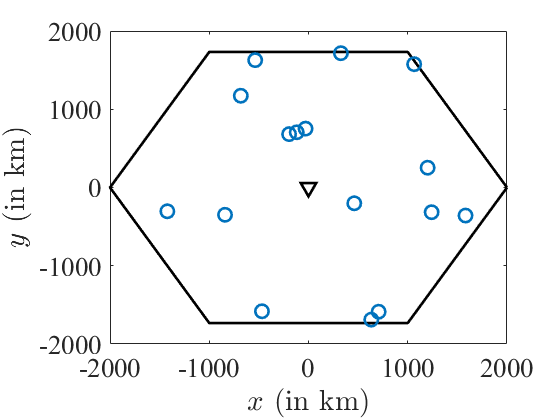

addpath('./functions/')

M = 64;                                                             % Number of antennas at the base station
K = 16;                                                              % Number of users at the cell
L = 4 ;                                                               % Number of selected users

N_schedule = ceil(K/L);
N_ALG = 7;

channel_type = 'rayleigh';

R = 2000;                                                            % Cell's raidus (circumradius) in meters
r = sqrt(3)/2*R;                                                     % Cell's inradius in meters

x_cell = [R R/2 -R/2 -R -R/2 R/2 R]';                                % Cell's x-coordinates
y_cell = [0 r    r    0 -r  -r   0]';                                % Cell's y-coordinates

commcell.nAntennas       = M;                                        % Number of Antennas
commcell.nUsers          = K;                                        % Number of Users
commcell.radius          = R;                                        % Cell's raidus (circumradius) in meters
commcell.bsHeight        = 32;                                       % Height of base station in meters
commcell.userHeight      = [1 2];                                    % Height of user terminals in meters ([min max])
commcell.nPaths          = 30;                                       % Number of Multipaths
commcell.frequency       = 1.9e9;                                    % Carrier frequency in Hz
commcell.meanShadowFad   = 0;                                        % Shadow fading mean in dB
commcell.stdDevShadowFad = 8;                                        % Shadow fading standard deviation in dB
commcell.city            = 'large';                                  % Type of city

tau_c = 15000;
tau_p = K;

settings.coherenceTime           = tau_c;                            % Coherence time in samples
settings.PilotTime               = tau_p;                            % Pilot time in samples
settings.uplinkDownlinkTimeRatio = 0.5;                              % Ratio between the uplink and downlink payload time
settings.bandwidth               = 20e6;                             % Sytem bandwidth in Hz
settings.cellArea                = 1;                                % Cell area in km^2

linkprop.bsPower         = 10;                                        % in Watts
linkprop.userPower       = 0.2;                                      % in Watts
linkprop.AntennaGainBS   = 0;                                        % in dBi
linkprop.AntennaGainUser = 0;                                        % in dBi
linkprop.noiseFigureBS   = 9;                                        % in dB
linkprop.noiseFigureUser = 9 ;                                       % in dB
linkprop.bandwidth       = 20e6;                                     % in Hz

[G,beta,user_pos] = massiveMIMOChannel(commcell,channel_type);

% beta_db = -148 - 37.6*log10(commcell.radius/1000);
% beta = 10^(beta_db/10)*ones(K,1);

[~,snr_db] = linkBudgetCalculation(linkprop);                        % SNR in dB
snr        = 10^((snr_db)/10);                                       % SNR
snr_eff    = snr*beta;

algorithm_type = {'exhaustive search equal power selection', ...
                  'exhaustive search max-min fairness selection', ...
                  'random selection', ...
                  'semi-orthogonal selection', ...
                  'correlation-based selection', ...
                  'ici-based selection', ...
                  'fr-based selection'};

% algorithm_type = {'random selection', ...
%                   'semi-orthogonal selection', ...
%                   'correlation-based selection', ...
%                   'ici-based selection', ...
%                   'fr-based selection'};


% Initialization

gamma_max_min = zeros(N_schedule,N_ALG);

thrgpt_epa_sel       = cell(N_schedule,N_ALG);
thrgpt_mmfpa_sel     = cell(N_schedule,N_ALG);

sum_thrgpt_epa_sel   = zeros(N_schedule,N_ALG);
sum_thrgpt_mmfpa_sel = zeros(N_schedule,N_ALG);

min_thrgpt_epa_sel   = zeros(N_schedule,N_ALG);
min_thrgpt_mmfpa_sel = zeros(N_schedule,N_ALG);

psi     = zeros(K,1);
psi_sel = zeros(L,N_ALG);

eta_sel = zeros(L,N_schedule);

G_sel = zeros(M,L,N_schedule,N_ALG);

user_sel  = cell(N_schedule,N_ALG);
user_drop = cell(N_schedule,N_ALG);

figure;

plot(x_cell,y_cell,'k','linewidth',linewidth);
hold on;
plot(0,0,'vk','linewidth',linewidth,'markersize',markersize);
plot(user_pos(:,1), user_pos(:,2),'o','color',color(1,:),'linewidth',linewidth,'markersize',markersize);

xlabel('$x$ (in km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$y$ (in km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

set(gca,'fontname',fontname,'fontsize',fontsize);
xlim([-R R]);
ylim([-R R]);

% No Selection

W = precoderMatrix(G,'mf');

[gamma_ns,eta] = maxMinFairness(G,beta,snr,'algorithm 2');

thrgput_epa   = throughput(G,W,1/K,'downlink',snr_eff,settings);
thrgput_mmfpa = throughput(G,W,eta,'downlink',snr_eff,settings);

sum_thrgput_epa = sum(thrgput_epa);
min_thrgput_epa = min(thrgput_epa,[],1);

sum_thrgput_mmfpa = sum(thrgput_mmfpa);
min_thrgput_mmfpa = min(thrgput_mmfpa,[],1);

% settings.coherenceTime = (tau_c - tau_p)/N_schedule;                   % Coherence time in samples
settings.PilotTime     = ((N_schedule - 1)*tau_c + tau_p)/N_schedule;    % Pilot time in samples

for alg_idx = 1:N_ALG
    G_bar = G;
    idx_bar = (1:K)';
    
    for n = 1:N_schedule
        if size(G_bar,2) >= L
            if alg_idx == 1
                [user_sel_aux,G_sel(:,:,n,alg_idx),user_drop_aux,G_drop] = exhaustiveSearchSelection(G_bar,beta(idx_bar),snr,L,settings,'MATCHED FILTER','EQUAL POWER ALLOCATION','SUM');
            elseif alg_idx == 2
                [user_sel_aux,G_sel(:,:,n,alg_idx),user_drop_aux,G_drop] = exhaustiveSearchSelection(G_bar,beta(idx_bar),snr,L,settings,'MATCHED FILTER','MAX-MIN FAIRNESS POWER ALLOCATION','MIN');
            else
                [user_sel_aux,G_sel(:,:,n,alg_idx),user_drop_aux,G_drop] = userSelector(G_bar,beta(idx_bar),algorithm_type{alg_idx},'fixed',L,[]);
            end
            
            pow_d_sel = ones(L,1)/L;
        else
            G_sel(:,:,n,alg_idx) = G_bar;
            
            user_sel_aux  = 1:rem(K,L);
            user_drop_aux = [];
            
            pow_d_sel = ones(size(G_bar,2),1)/size(G_bar,2);
        end
        
        if n > 1
            user_sel{n,alg_idx}  = user_drop{n-1,alg_idx}(user_sel_aux);
            user_drop{n,alg_idx} = user_drop{n-1,alg_idx}(user_drop_aux);
        else
            user_sel{n,alg_idx}  = user_sel_aux;
            user_drop{n,alg_idx} = user_drop_aux;
        end
                
        G_bar = G_drop;
        idx_bar = user_drop{n,alg_idx};
        
        W = precoderMatrix(G_sel(:,:,n,alg_idx),'mf');
        
        [gamma_max_min(n,alg_idx),eta_sel(:,n)] = maxMinFairness(G_sel(:,:,n,alg_idx),beta(user_sel{n,alg_idx}),snr,'algorithm 2');
        
        thrgpt_epa_sel{n,alg_idx}   = throughput(G_sel(:,:,n,alg_idx),W,pow_d_sel,'downlink',snr_eff(user_sel{n,alg_idx}),settings);
        thrgpt_mmfpa_sel{n,alg_idx} = throughput(G_sel(:,:,n,alg_idx),W,eta_sel(:,n),'downlink',snr_eff(user_sel{n,alg_idx}),settings);
        
        sum_thrgpt_epa_sel(n,alg_idx) = sum(thrgpt_epa_sel{n,alg_idx});
        min_thrgpt_epa_sel(n,alg_idx) = min(thrgpt_epa_sel{n,alg_idx},[],1);
        
        sum_thrgpt_mmfpa_sel(n,alg_idx) = sum(thrgpt_mmfpa_sel{n,alg_idx});
        min_thrgpt_mmfpa_sel(n,alg_idx) = min(thrgpt_mmfpa_sel{n,alg_idx},[],1);
    end   
end

b = zeros(N_schedule,1);
b(1) = 0.5*(tau_c - tau_p);

min_thrgpt_schdl = zeros(N_schedule,N_ALG);

for alg_idx = 1:N_ALG
    A = [1 1 1 1; log2(1 + gamma_max_min(1,alg_idx)) -log2(1 + gamma_max_min(2,alg_idx)) 0 0; 0 log2(1 + gamma_max_min(2,alg_idx)) -log2(1 + gamma_max_min(3,alg_idx)) 0; 0 0 log2(1 + gamma_max_min(3,alg_idx)) -log2(1 + gamma_max_min(4,alg_idx))];
    tau = A\b;
    
    min_thrgpt_schdl(:,alg_idx) = settings.bandwidth*(tau/tau_c).*log2(1 + gamma_max_min(:,alg_idx));
end

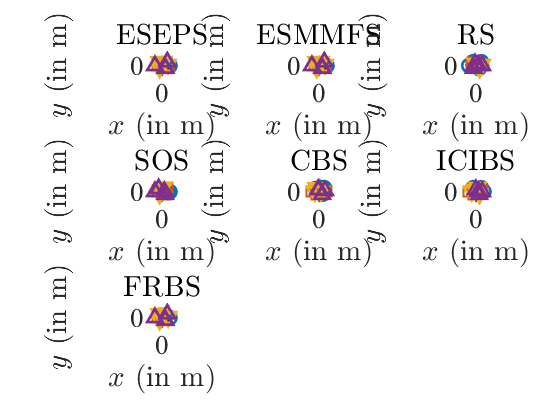

figure;

for alg_idx = 1:length(legend_algo_2)
    subplot(3,3,alg_idx);
    
    plot(x_cell,y_cell,'k','linewidth',linewidth);
    hold on;
    plot(0,0,'vk','linewidth',linewidth,'markersize',markersize);
    for n = 1:N_schedule
        plot(user_pos(user_sel{n,alg_idx},1), user_pos(user_sel{n,alg_idx},2),marker{n},'color',color(n,:),'linewidth',linewidth,'markersize',markersize);
    end
    hold off;
    
    xlabel('$x$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
    ylabel('$y$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
    
    title(legend_algo_2{alg_idx},'fontname',fontname,'fontsize',fontsize,'interpreter','latex');
    
    set(gca,'fontname',fontname,'fontsize',fontsize);
    
    xlim([-R R]);
    ylim([-R R]);
end

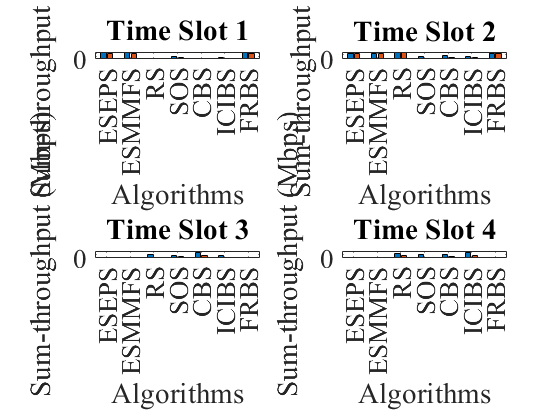

figure;

for n = 1:N_schedule
    subplot(2,2,n);
    
    bar(cat_2,1e-6*[sum_thrgpt_epa_sel(n,:)' sum_thrgpt_mmfpa_sel(n,:)']);
    
    xlabel('Algorithms','fontname',fontname,'fontsize',fontsize);
    ylabel('Sum-throughput (Mbps)','fontname',fontname,'fontsize',fontsize);
    
    title(['Time Slot ' num2str(n)],'fontname',fontname,'fontsize',fontsize);
    
    % legend(legend_pa,'fontname',fontname,'fontsize',fontsize);
    
    set(gca,'fontname',fontname,'fontsize',fontsize);
end

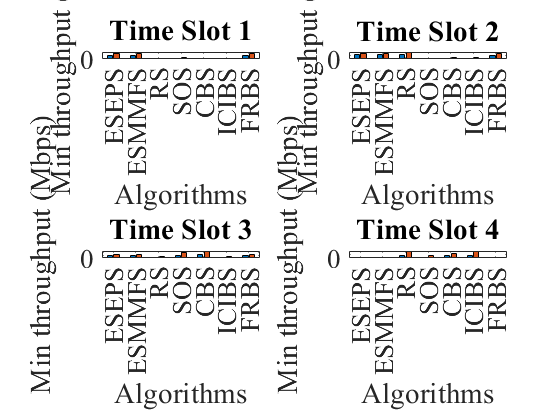

figure;

for n = 1:N_schedule
    subplot(2,2,n);
    
    bar(cat_2,1e-6*[min_thrgpt_epa_sel(n,:)' min_thrgpt_mmfpa_sel(n,:)']);
    
    xlabel('Algorithms','fontname',fontname,'fontsize',fontsize);
    ylabel('Min throughput (Mbps)','fontname',fontname,'fontsize',fontsize);
    
    title(['Time Slot ' num2str(n)],'fontname',fontname,'fontsize',fontsize);
    
    % legend(legend_pa,'fontname',fontname,'fontsize',fontsize);
    
    set(gca,'fontname',fontname,'fontsize',fontsize);
end

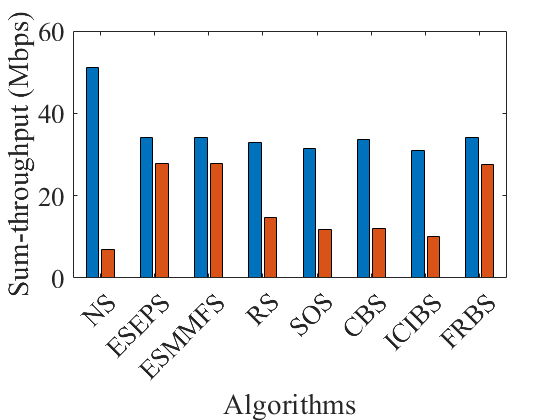

figure;

bar(cat_1,1e-6*[sum_thrgput_epa sum_thrgput_mmfpa; sum(sum_thrgpt_epa_sel,1)' sum(sum_thrgpt_mmfpa_sel,1)']);

xlabel('Algorithms','fontname',fontname,'fontsize',fontsize);
ylabel('Sum-throughput (Mbps)','fontname',fontname,'fontsize',fontsize);

% legend(legend_pa,'fontname',fontname,'fontsize',fontsize,'location','northwest');

% ylim([0 7]);

set(gca,'fontname',fontname,'fontsize',fontsize);

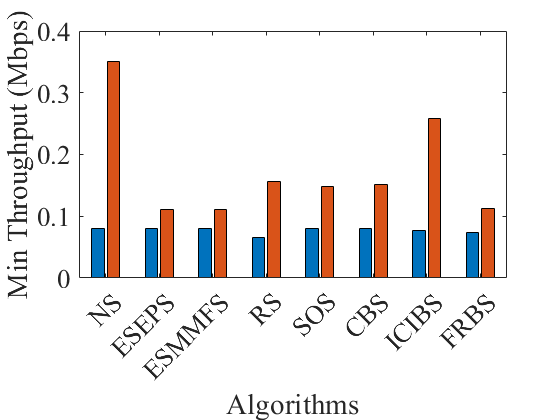

figure;

bar(cat_1,1e-6*[min_thrgput_epa min_thrgput_mmfpa; min(min_thrgpt_epa_sel,[],1)' min(min_thrgpt_mmfpa_sel,[],1)']);

xlabel('Algorithms','fontname',fontname,'fontsize',fontsize);
ylabel('Min Throughput (Mbps)','fontname',fontname,'fontsize',fontsize);

% legend(legend_pa,'fontname',fontname,'fontsize',fontsize,'location','northwest');

set(gca,'fontname',fontname,'fontsize',fontsize);

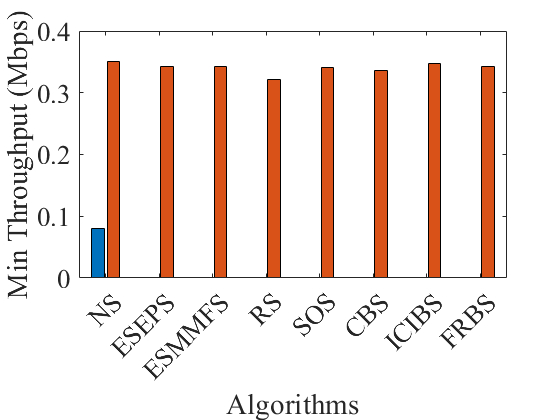

figure;

bar(cat_1,1e-6*[min_thrgput_epa min_thrgput_mmfpa; zeros(N_ALG,1) min_thrgpt_schdl(1,:)']);

xlabel('Algorithms','fontname',fontname,'fontsize',fontsize);
ylabel('Min Throughput (Mbps)','fontname',fontname,'fontsize',fontsize);

% legend(legend_pa,'fontname',fontname,'fontsize',fontsize,'location','northwest');

set(gca,'fontname',fontname,'fontsize',fontsize);

function [user_sel,sel_chnl_mtx,varargout] = exhaustiveSearchSelection(chnl_mtx,lrg_scl,snr,n_selected,settings,precoding,power_control,cost_func)

n_user    = size(chnl_mtx,2);                                              % Number users

all_comb = nchoosek(1:n_user,n_selected);
N_all    = size(all_comb,1);

thrghpt_aux = zeros(n_selected,N_all);

switch precoding
    case 'MATCHED FILTER'
        switch power_control
            case 'EQUAL POWER ALLOCATION'
                for n = 1:N_all
                    chnl_mtx_aux = chnl_mtx(:,all_comb(n,:));
                    lrg_scl_aux  = lrg_scl(all_comb(n,:));
                    
                    W = precoderMatrix(chnl_mtx_aux,'mf');
                    
                    thrghpt_aux(:,n) = throughput(chnl_mtx_aux,W,1/n_selected,'downlink',snr*lrg_scl_aux,settings);
                end
                
                switch cost_func
                    case 'SUM'
                        [~,idx_opt] = max(sum(thrghpt_aux,1));
                        
                        user_sel     = all_comb(idx_opt,:);
                        sel_chnl_mtx = chnl_mtx(:,all_comb(idx_opt,:));
                        thrghpt      = thrghpt_aux(:,idx_opt);
                    case 'MIN'
                        [~,idx_opt]  = max(min(thrghpt_aux,[],1));
                        
                        user_sel     = all_comb(idx_opt,:);
                        sel_chnl_mtx = chnl_mtx(:,all_comb(idx_opt,:));
                        thrghpt      = thrghpt_aux(:,idx_opt);
                    otherwise
                        error('Invalid cost function');
                end
                
                user_drop = (1:n_user)';
                user_drop(user_sel) = [];
                    
                drop_chnl_mtx = chnl_mtx;
                drop_chnl_mtx(:,user_sel) = [];
                
                varargout{1} = user_drop;
                varargout{2} = drop_chnl_mtx;
                varargout{3} = thrghpt;
            case 'MAX-MIN FAIRNESS POWER ALLOCATION'
                for n = 1:N_all
                    chnl_mtx_aux = chnl_mtx(:,all_comb(n,:));
                    lrg_scl_aux  = lrg_scl(all_comb(n,:));
                    
                    W = precoderMatrix(chnl_mtx_aux,'mf');
                    
                    [~,eta] = maxMinFairness(chnl_mtx_aux,lrg_scl_aux,snr,'algorithm 2');
                    
                    thrghpt_aux(:,n) = throughput(chnl_mtx_aux,W,eta,'downlink',snr*lrg_scl_aux,settings);
                end
                
                switch cost_func
                    case 'SUM'
                        [~,idx_opt] = max(sum(thrghpt_aux,1));
                        
                        user_sel     = all_comb(idx_opt,:);
                        sel_chnl_mtx = chnl_mtx(:,all_comb(idx_opt,:));
                        thrghpt      = thrghpt_aux(:,idx_opt);
                    case 'MIN'
                        [~,idx_opt]  = max(min(thrghpt_aux,[],1));
                        
                        user_sel     = all_comb(idx_opt,:);
                        sel_chnl_mtx = chnl_mtx(:,all_comb(idx_opt,:));
                        thrghpt      = thrghpt_aux(:,idx_opt);
                    otherwise
                        error('Invalid cost function');
                end
                
                user_drop = (1:n_user)';
                user_drop(user_sel) = [];
                
                drop_chnl_mtx = chnl_mtx;
                drop_chnl_mtx(:,user_sel) = [];
                
                varargout{1} = user_drop;
                varargout{2} = drop_chnl_mtx;
                varargout{3} = thrghpt;                
            otherwise
                error('Invalid power-control policy');
        end
    case 'ZERO-FORCING'
    otherwise
        error('Invalid Precoding');
end

end